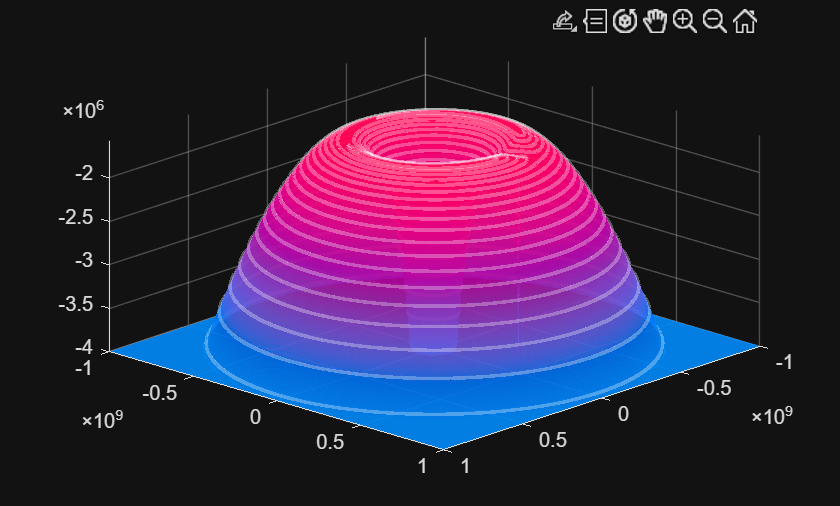

clear all;
syms t X Y Ut(x,y) U(x,y)
G   = 6.674e-11;
Ms  = 1.989e30;
Mj  = 1.898e27;
Me  = 5.972e24;
Mm  = 7.347e22;
Rj0 = 7.770e11;
Re0 = 1.496e11;
Rm0 = 3.840e8;
Vj0 = 13.1e3;
Ve0 = 29.8e3;
Vm0 = 1.03e3;
Oj0 = Vj0/Rj0;
Oe0 = Ve0/Re0;
Om0 = Vm0/Rm0;
Xe  = - Mm*Rm0/Me;
Ye  = 0;
Xm  = Rm0;
Ym  = 0;

reserr = 2;
res = 1e7;
x = -1e9:res:1e9;
y = -1e9:res:1e9;
[Xd,Yd] = meshgrid(x,y);

t = 2;

Xm  = Rm0*cos(t);
Ym  = Rm0*sin(t);
Xe  =-Mm*Rm0/Me*cos(t);
Ye  =-Mm*Rm0/Me*sin(t);
U(X,Y) =  -.5*(X^2+Y^2)*Om0^2-G.*(Me/sqrt((Xe-X)^2+(Ye-Y)^2)+Mm/sqrt((Xm-X)^2+(Ym-Y)^2));
UMat = matlabFunction(simplify(U));
Ux = matlabFunction(simplify(diff(U,X)));
Uy = matlabFunction(simplify(diff(U,Y)));
Z = UMat(Xd,Yd);
[N,edges] = histcounts(Z,1000);
Zc = (clip(Z,max([Z(1,:) Z(end,:) Z(:,1)' Z(:,end)']),0));
Zcm = (Zc == Z);
Zmc = (clip((Ux(Xd,Yd).^2)+(Uy(Xd,Yd).^2),0,.0001));
pclip = 15;

Ztp = (Zmc<prctile(Zmc(Z>edges(end-3)),pclip)&(Z>edges(end-3)));
Ztp = (imtophat(Ztp,strel('disk',1))+imerode(Ztp,strel('disk',reserr)))>0;
MLM = [Xd(Ztp), Yd(Ztp)];
MLMS = zeros(size(MLM));
for i=1:size(MLM,1)
MLMS(i,:) = fsolve(@(r)[Ux(r(1),r(2))^2,Uy(r(1),r(2))^2]*10000,[MLM(i,1),MLM(i,2)],optimoptions('fsolve','Display','off'));
end

colormap nebula;
axis tight;
surf(Xd,Yd,Zc,'EdgeColor','none', 'FaceAlpha',0.9);
hold on;
contour3(Xd,Yd,Zc,prctile(Zc(:),100*(.01:.05:1).^.5),'w','LineWidth',2,'EdgeAlpha',0.3);
hold off;
view([55 45])

drawnow;


